plecs

   USAGE: PLECS('CMD','PARAMETER1','PARAMETER2',...)
     Known commands are: get, set, version, hostid, thermal, scope, checkout


fg = 50; %[Hz] Frecuencia red
Tg = 1 / fg %[s]

Tg = 0.0200

ft = 20 * fg %[Hz] Frecuencia triangular

ft = 1000

Tt = 1 / ft %[s]

Tt = 1.0000e-03

m = 1; % |V*|
Nt = 3; % Cantidad de SM = Cantidad de carriers
%[Hz] Frecuencia de muestro
% fs = ft * 10.59 % Se ve bien ia integrada en la simulación
% fs = ft * 3.2
% Frec. de Nyquist:
% f_sampleo >= 2*N*f_carrier
fs = (ft * 100 * Nt)

fs = 300000

Ts = 1 / fs %[s]

Ts = 3.3333e-06

Va = 100 * sqrt(2); %[V] Tensión red
Vcc = Va / sqrt(2); %[V] Tensión bus DC
C = 1e-3; %[F] Condensador SM
L = 1e-3; %[H] Inductancia serie
R = 1e-3; %[Ohm] Resistencia serie
Z = 10; %[Ohm] Carga

max_step_size = (1 / ft) / 100

max_step_size = 1.0000e-05

if Ts < max_step_size
    max_step_size = Ts %[s]
end

max_step_size = 3.3333e-06

out = sim("x7L_CHB/x7L_CHB.slx", 0.2);
t = out.ia.Time;

Corrientes

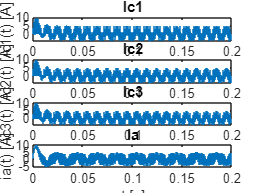

% Condensadores
clf
subplot(4, 1, 1)
plot(out.ic1)
title("Ic1")
xlabel("t [s]")
ylabel("ic1(t) [A]")

subplot(4, 1, 2)
plot(out.ic2)
title("Ic2")
xlabel("t [s]")
ylabel("ic2(t) [A]")

subplot(4, 1, 3)
plot(out.ic3)
title("Ic3")
xlabel("t [s]")
ylabel("ic3(t) [A]")

% Carga
subplot(4, 1, 4)
plot(out.ia)
title("Ia")
xlabel("t [s]")
ylabel("ia(t) [A]")

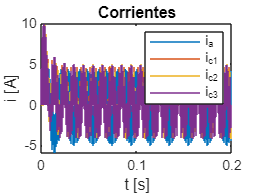


clf
plot(out.ia)
hold on
plot(out.ic1)
plot(out.ic2)
plot(out.ic3)
hold off
title("Corrientes")
xlabel("t [s]")
ylabel("i [A]")
legend("i_{a}", "i_{c1}", "i_{c2}", "i_{c3}")

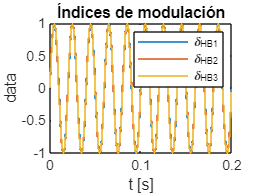

% Índices de modulación
clf
plot(out.d1)
hold on
plot(out.d2)
plot(out.d3)
hold off
title("Índices de modulación")
xlabel("t [s]")
legend("\delta_{HB1}", "\delta_{HB2}", "\delta_{HB3}")

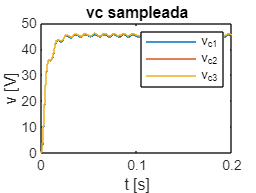


% Tensión de los condensadores
clf
plot(out.vc1)
hold on
plot(out.vc2)
plot(out.vc3)
title("vc sampleada")
xlabel("t [s]")
ylabel("v [V]")
hold off
legend("v_{c1}", "v_{c2}", "v_{c3}")

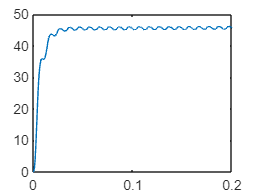

% Cálculo de Vc según modelo dinámico discreto
N = length(t); % Horizonte de predicción
vc1_md = zeros(N, 1); % Tensión del condensador 1 según modelo discreto
vc2_md = zeros(N, 1);
vc3_md = zeros(N, 1);
v = zeros(N, 1);
ia_s = out.ia.Data; % Corriente de la carga sampleada con ZOH
d1_s = out.d1.Data; % Índice de modulación discretizado
d2_s = out.d2.Data;
d3_s = out.d3.Data;
ic1_s = out.ic1.Data;
for k = 1 : N - 1
    vc1_md(k + 1) = vc1_md(k) + Ts / C * ia_s(k) * d1_s(k);
    vc2_md(k + 1) = vc2_md(k) + Ts / C * ia_s(k) * d2_s(k);
    vc3_md(k + 1) = vc3_md(k) + Ts / C * ia_s(k) * d3_s(k);
    % Esta es mejor (v) con una frec de sampleo muy alta, pero a la larga
    % igual diverge
    v(k + 1) = v(k) + Ts / C * ic1_s(k);
end

clf
plot(t, v)

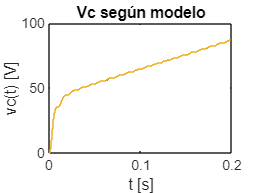


clf
stairs(t, vc1_md)
hold on
stairs(t, vc2_md)
stairs(t, vc3_md)
hold off
title("Vc según modelo")
xlabel("t [s]")
ylabel("vc(t) [V]")

Comparación entre predicción del modelo discreto y tensiones sampleadas

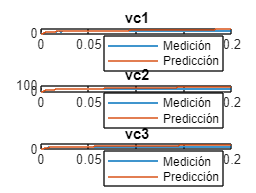

clf
subplot(3, 1, 1)
plot(out.vc1)
hold on
stairs(t, vc1_md)
title("vc1")
xlabel("t [s]")
ylabel("v [V]")
legend("Medición", "Predicción")

subplot(3, 1, 2)
plot(out.vc2)
hold on
stairs(t, vc2_md)
title("vc2")
xlabel("t [s]")
ylabel("v [V]")
legend("Medición", "Predicción")

subplot(3, 1, 3)
plot(out.vc3)
hold on
stairs(t, vc3_md)
title("vc3")
xlabel("t [s]")
ylabel("v [V]")
legend("Medición", "Predicción")

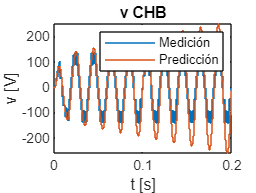


clf
plot(out.vchb)
hold on
stairs(t, vc1_md .* d1_s + vc2_md .* d2_s + vc3_md .* d3_s)
title("v CHB")
xlabel("t [s]")
ylabel("v [V]")
legend("Medición", "Predicción")

Gráfica con tiempo de muestreo de 2*N*f_carrier

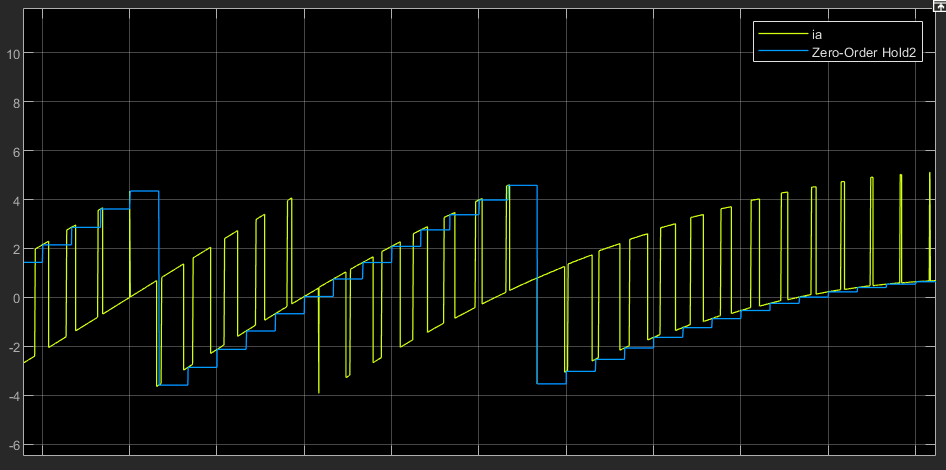

Estrategia del observador

1) Cálculo del error

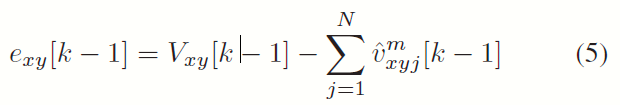

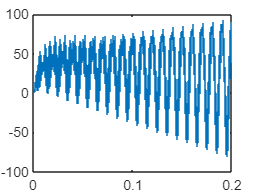

vchb_md = vc1_md .* d1_s + vc2_md .* d2_s + vc3_md .* d3_s; % Ecuación 6
vchb_d = out.vchb.Data; % Tensión del convertidor medida
e = vchb_d - vchb_md; % Ecuación 5
e1 = e .* d1_s; % Ecuación 7
e2 = e .* d2_s;
e3 = e .* d3_s;

clf
stairs(t, vc1_md + e1)